# Test Mappings

clear vars; close all; clc;
warning('off','all')

% Number of observables
numObs = 15;
% Define dimension of modes
SSMDim = 6; hSSMDim = SSMDim/2;
rdof = hSSMDim; odof = rdof;
load obsDecayDataC

## Visualize Training Data

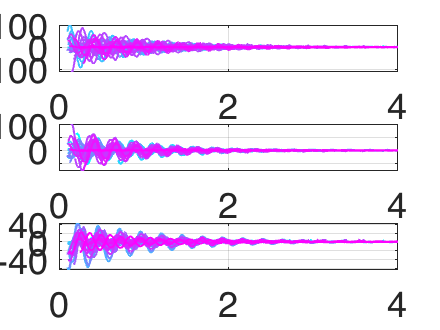

trajs = [13, 14, 15];
numCoord = length(trajs);
customFigure('subPlot',[numCoord 1]);
labels = ["$x_a$", "$y_a$", "$z_a$", ...
    "$x_b$", "$y_b$", "$z_b$", ...
    "$x_c$", "$y_c$", "$z_c$", ...
    "$x_d$", "$y_d$", "$z_d$", ...
    "$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:numCoord
    subplot(numCoord,1,iPlt); colororder(cool(size(oData, 1)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(trajs(iPlt)),'Interpreter','latex');
end

for iTraj = 1:size(oData, 1)
    for iObs = 1:numCoord
        subplot(numCoord,1,iObs);
        plot(oData{iTraj,1},oData{iTraj,2}(trajs(iObs),:),'Linewidth',1)
    end
end

Consider only the tip positions, neglect other sensor data in this script.

tipData = oData;
Ts = 1/(tipData{iTraj,1}(2)-tipData{iTraj,1}(1));
freqHz = 15;
for iTraj = 1:size(oData, 1)
    tipData{iTraj,2} = oData{iTraj,2}(trajs,:);%transpose(lowpass(transpose(oData{iTraj,2}(trajs,:)), freqHz, Ts));
end

Visualize filtered data

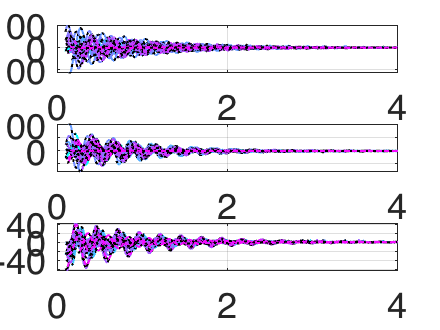

trajs = [13, 14, 15];
numCoord = length(trajs);
customFigure('subPlot',[numCoord 1]);
labels = ["$x_a$", "$y_a$", "$z_a$", ...
    "$x_b$", "$y_b$", "$z_b$", ...
    "$x_c$", "$y_c$", "$z_c$", ...
    "$x_d$", "$y_d$", "$z_d$", ...
    "$x_e$", "$y_e$", "$z_e$"];
for iPlt = 1:numCoord
    subplot(numCoord,1,iPlt); colororder(cool(size(oData, 1)));
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(trajs(iPlt)),'Interpreter','latex');
end

for iTraj = 1:size(oData, 1)
    for iObs = 1:numCoord
        subplot(numCoord,1,iObs);
        plot(oData{iTraj,1},oData{iTraj,2}(trajs(iObs),:),'Linewidth',1)
        plot(tipData{iTraj,1},tipData{iTraj,2}(iObs,:), 'k:', 'Linewidth',1)
    end
end

Perform delay-embedding. As observables for the model, we consider the current tip position data as well as past measurements (no future ones) of the tip position data. For this case (we only consider the tip), we have a minimum of `4` delays, which is augmented by the `overEmbed` variable, so that the number of total delays is `4+overEmbed`. We also do some cutting, but it is not necessary in this current case.

overEmbed = 5;
[yData, opts_embd] = coordinatesEmbeddingControl(tipData, SSMDim, 'OverEmbedding', overEmbed);

The 30 embedding coordinates consist of the 3 measured states and their 9 time-delayed measurements.


embedDim = size(yData{1,2},1);
outdofs = [embedDim-2 embedDim-1 embedDim];
sliceInt = [0.01, Inf];
yDataTrunc = sliceTrajectories(yData, sliceInt);

## Visualize Autonomous Data

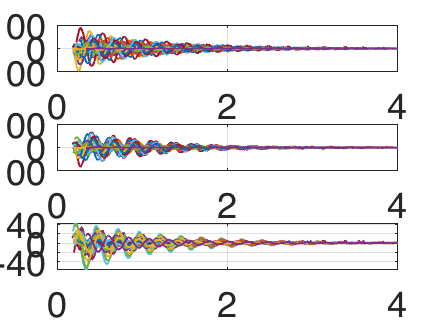

% Filtering parameters
Ts = 1/(yDataTrunc{iTraj,1}(2)-yDataTrunc{iTraj,1}(1));
freqAutVelHz = 0.1;
freqAutPosHz = 5;

% Plot autonomous data (Visualize position)
labels = ["$x_e$", "$y_e$", "$z_e$"];
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
for iPlt = 1:length(outdofs)
    subplot(numCoord,1,iPlt);
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
for iTraj = 1:size(yDataTrunc, 1)
    for iObs = 1:length(outdofs)
        subplot(numCoord,1,iObs);
        plot(yDataTrunc{iTraj,1},yDataTrunc{iTraj,2}(outdofs(iObs),:),'Linewidth',1)
    end
end


autVelocity = yDataTrunc;
for iTraj = 1:size(autVelocity, 1)
    [velocities,displacements,time] = finiteTimeDifference(...
        transpose(lowpass(transpose(yDataTrunc{iTraj,2}(end-2:end,:)),freqAutPosHz, Ts)),...
        yDataTrunc{iTraj,1},diff_range);
    %velocities = transpose(lowpass(transpose(velocities),freqAutVelHz, Ts));
    autVelocity{iTraj, 1} = time;
    autVelocity{iTraj, 2} = velocities;
end

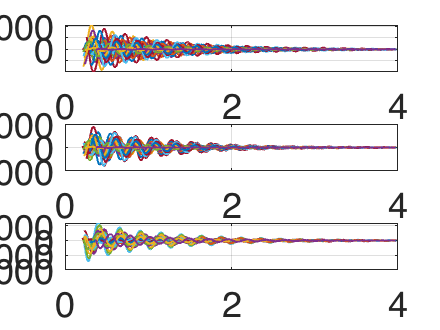

velDofs = [1 2 3];
% Plot data
figure;
labels = ["$x_e$", "$y_e$", "$z_e$"];
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
for iPlt = 1:length(outdofsNew)
    subplot(numCoord,1,iPlt);
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
for iTraj = 1:size(autVelocity, 1)
    for iObs = 1:length(velDofs)
        subplot(numCoord,1,iObs);
        plot(autVelocity{iTraj,1},autVelocity{iTraj,2}(velDofs(iObs),:),'Linewidth',1)
    end
end

## Visualize controlled data

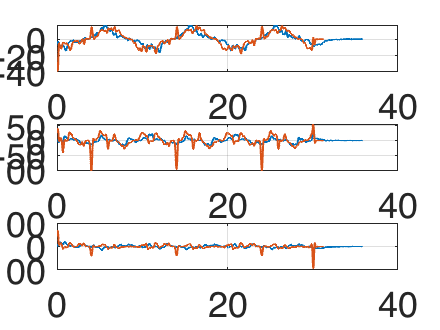

diff_range = 3;
trajs = [13, 14, 15];
numCoord = length(trajs);
outdofsNew = [4 5 6];

zu = {};
% Load and process lower amplitude Figure 8 for tip coords only
load figure8_amp15
%load koopman_data_figureEight
y = y(13:end, :); % only tip displacements

keptIdxs = 1:size(y,2);
zu{1,1} = t(keptIdxs); zu{1,2} = y(:, keptIdxs) - y(:, end); 
uCell{1,1} = t(keptIdxs); uCell{1,2} = u(:, keptIdxs); 

% Load and process lower amplitude Figure 8 for tip coords only
load figure8_amp20
%load koopman_data_figureEight
y = y(13:end, :); % only tip displacements

keptIdxs = 1:size(y,2);
zu{2,1} = t(keptIdxs); zu{2,2} = y(:, keptIdxs) - y(:, end); 
uCell{2,1} = t(keptIdxs); uCell{2,2} = u(:, keptIdxs); 

% Store in queries cells
Yu = zu; Udelay = uCell;

% Filtering parameters
Ts = 1/(t(2)-t(1));
freqVelHz = 0.1;
freqPosHz = 1;

for iTraj = 1:size(Yu, 1)
%     [velocities,displacements,time] = finiteTimeDifference(...
%         zu{iTraj,2},...
%         zu{iTraj,1}(2:end),diff_range);
    [velocities,displacements,time] = finiteTimeDifference(...
        transpose(lowpass(transpose(zu{iTraj,2}),freqPosHz, Ts)),...
        zu{iTraj,1}(2:end),diff_range);
    Yu{iTraj,1} = time;
    Yu{iTraj,2} = [displacements; transpose(lowpass(transpose(velocities),freqVelHz, Ts))];
%     Yu{iTraj,2} = [displacements; velocities];
    Udelay{iTraj,1} = uCell{iTraj,1}(1+diff_range:end-diff_range); 
    Udelay{iTraj,2} = uCell{iTraj,2}(:,1+diff_range:end-diff_range); 
end

% Plot data
labels = ["$x_e$", "$y_e$", "$z_e$"];
customFigure('subPlot',[numCoord 1]);
subplot(numCoord,1,1);
for iPlt = 1:length(outdofsNew)
    subplot(numCoord,1,iPlt);
    xlabel('$t$','Interpreter','latex');
    ylabel(labels(iPlt),'Interpreter','latex');
end
for iTraj = 1:size(Yu, 1)
    for iObs = 1:length(outdofsNew)
        subplot(numCoord,1,iObs);
        plot(Yu{iTraj,1},Yu{iTraj,2}(outdofsNew(iObs),:),'Linewidth',1)
    end
end